# DWT/Bagged Trees Model Optimizer

This script optimizes the accuracy performance of a Bootstrap aggregating tree classification model for the discrete wavelet transform features using the 5-level Coiflets 2 wavelet with 4 principle components of Shannon entropy, and the subband statistics of the coefficients at each of the level.

## Load data

The features are all numeric and stored in 'xfeatures', the responses are store in 'xresponse'. The variable 'XTrain' is a numeric array combining the features and responses. 

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesWavelets_coif2_Lvl4_T2_nohampel.mat"; 
load(fullfile(featuredir,featurefilename));
xresponses = logical(xresponses);

% Find model directory
basedir = fileparts(pwd)

basedir = '/Users/rahulbirmiwal/Documents/UWMSDS/Capstone/EnvNoiseDetector'

modeldir = fullfile(basedir,"data","Models");

% Create pool of MATLAB workers
%tic; parpool('local',2); toc

## Train model

Use the built-in hyperparameter optimization for model optimization. Results do vary do to random selection of data and variables in the initial stages of building the model. 

Copying objective function to workers...
Done copying objective function to workers.


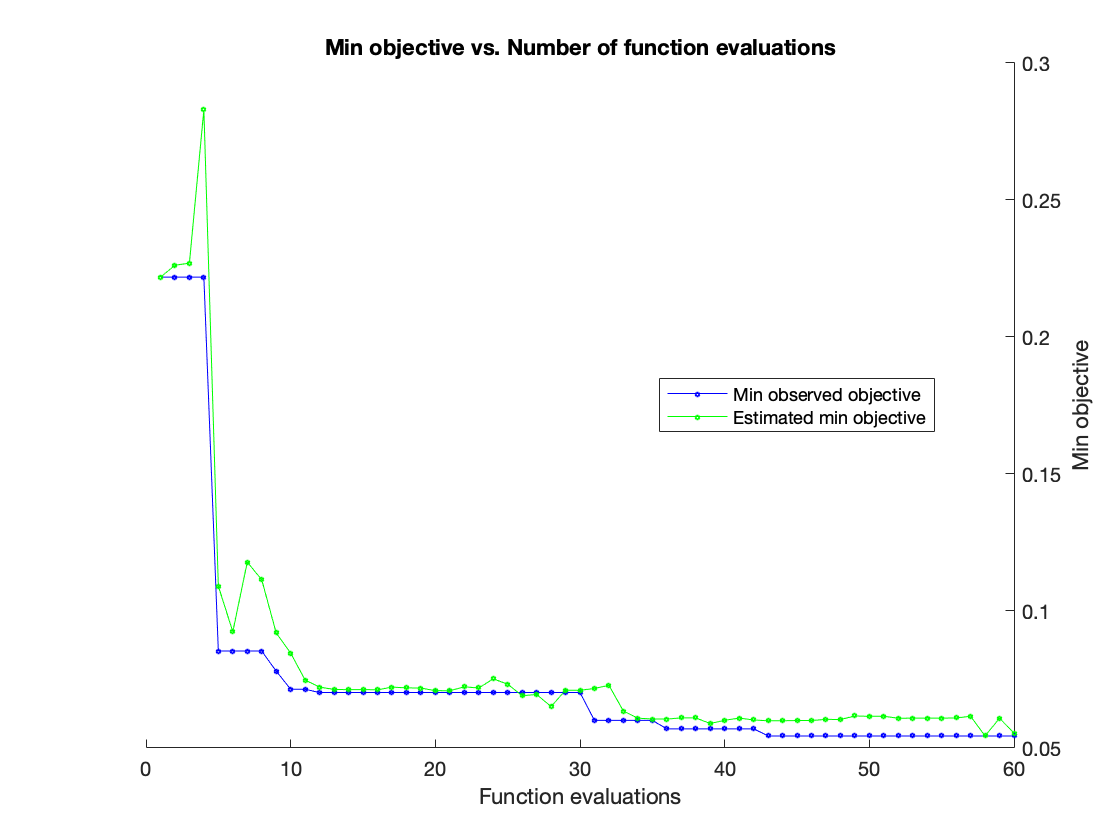

|==========================================================================================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | on           | ToSample     |
|==========================================================================================================================================================================================|
|    1 |       2 | Best   |     0.22185 |      4.4434 |     0.22185 |     0.22185 |   LogitBoost |           16 |      0.12082 |            2 |            2 |            - |            - |
|    2 |       2 | Accept |      0.2921 |        5.11 |

% Train model
useparpool = ~isempty(gcp);

classificationEnsemble = fitcensemble(...
    xfeatures, ...
    xresponses, ...
    'OptimizeHyperparameters','all', ...
    'HyperparameterOptimizationOptions',struct('UseParallel',useparpool,'MaxObjectiveEvaluations',60,'KFold',5));


% {'NumLearningCycles','LearnRate','MaxNumSplits','MinLeafSize','NumVariablesToSample','SplitCriterion}

% Create the result struct with predict function
trainedClassifier.predictFcn = @(x) predict(classificationEnsemble, x);

% Add additional fields to the result struct
trainedClassifier.ClassificationEnsemble = classificationEnsemble;
trainedClassifier.About = 'This struct is a trained model from trainBaggedTrees function.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 49 columns because this model was trained using 49 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');


xpred = oobPredict(classificationEnsemble);
[acc,fpr,fnr,f1] = scoreModel(xresponses,xpred);
trainedClassifier.Performance.Accuracy = acc;
trainedClassifier.Performance.F1score = f1;
trainedClassifier.Performance.FalsePostiveRate = fpr;
trainedClassifier.Performance.FalseNegativeRate = fnr;


## Save model

Save the model for future use.

% Save model
save(fullfile(modeldir,'ModelBaggedTreesDWPT4Lvl_Optimized.mat'),'trainedClassifier','featurefilename','featuredir','modeldir');